SID = 810199497;

x = 1:100;
y = zeros(1, 100);

for i = 1:100
    y(1, i) = sensor(i, SID);
    for j = 1:100:8
    disp(y(1, i));
    end
end

   28.3146

  172.9000

  935.8813

   3.5861e+03

   1.0551e+04

   2.5802e+04

   5.5235e+04

   1.0706e+05

   1.9217e+05

   3.2456e+05

   5.2167e+05

   8.0479e+05

   1.1994e+06

   1.7358e+06

   2.4489e+06

   3.3793e+06

   4.5734e+06

   6.0834e+06

   7.9685e+06

    10294528

   1.3135e+07

   1.6570e+07

   2.0689e+07

   2.5589e+07

   3.1377e+07

   3.8168e+07

   4.6087e+07

   5.5269e+07

   6.5860e+07

   7.8015e+07

   9.1903e+07

   1.0770e+08

   1.2560e+08

   1.4581e+08

   1.6853e+08

   1.9401e+08

   2.2248e+08

   2.5419e+08

   2.8942e+08

   3.2846e+08

   3.7160e+08

   4.1915e+08

   4.7146e+08

   5.2886e+08

   5.9172e+08

   6.6043e+08

   7.3537e+08

   8.1696e+08

   9.0565e+08

   1.0019e+09

   1.1061e+09

   1.2188e+09

   1.3406e+09

   1.4719e+09

   1.6132e+09

   1.7653e+09

   1.9285e+09

   2.1037e+09

   2.2913e+09

   2.4921e+09

   2.7068e+09

   2.9360e+09

   3.1804e+09

   3.4409e+09

   3.7182e+09

   4.0130e+09

   4.3263e+09

   4.

dataset = [x; y]

dataset = 	1.0e+10 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0017    0.0021    0.0026    0.0031    0.0038    0.0046    0.0055    0.0066    0.0078    0.0092    0.0108    0.0126    0.0146    0.0169    0.0194    0.0222    0.0254    0.0289    0.0328    0.0372    0.0419    0.0471    0.0529    0.0592    0.0660    0.0735    0.0

[train, val, test] = dividerand(size(dataset, 2), 0.8, 0, 0.2);

x_train = dataset(1, train)

x_train =      2     3     4     5     6     7     9    10    11    12    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    31    32    33    34    35    36    37    38    39    40    41    43    44    45    47    48    49    51    52    53    55    56    57    58    59


y_train = dataset(2, train)

y_train = 	1.0e+10 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0010    0.0013    0.0017    0.0021    0.0026    0.0031    0.0038    0.0046    0.0055    0.0092    0.0108    0.0126    0.0146    0.0169    0.0194    0.0222    0.0254    0.0289    0.0328    0.0372    0.0471    0.0529    0.0592    0.0735    0.0817    0.0906    0.1106    0.1219    0.1341    0.1613    0.1765    0.1929    0.2104    0.2291


x_test = dataset(1, test)

x_test =      1     8    13    29    30    42    46    50    54    65    67    69    70    83    85    86    87    90    93    96


y_test = dataset(2, test)

y_test = 	1.0e+10 *

    0.0000    0.0000    0.0001    0.0066    0.0078    0.0419    0.0660    0.1002    0.1472    0.3718    0.4326    0.5012    0.5385    1.2619    1.4214    1.5070    1.5966    1.8915    2.2284    2.6116



normalized_trainx = normalize(x_train);
normalized_trainy = normalize(y_train);

normalized_testx = (x_test - mean(x_train)) / std(x_train);
normalized_testy = (x_test - mean(y_train)) / std(y_train);

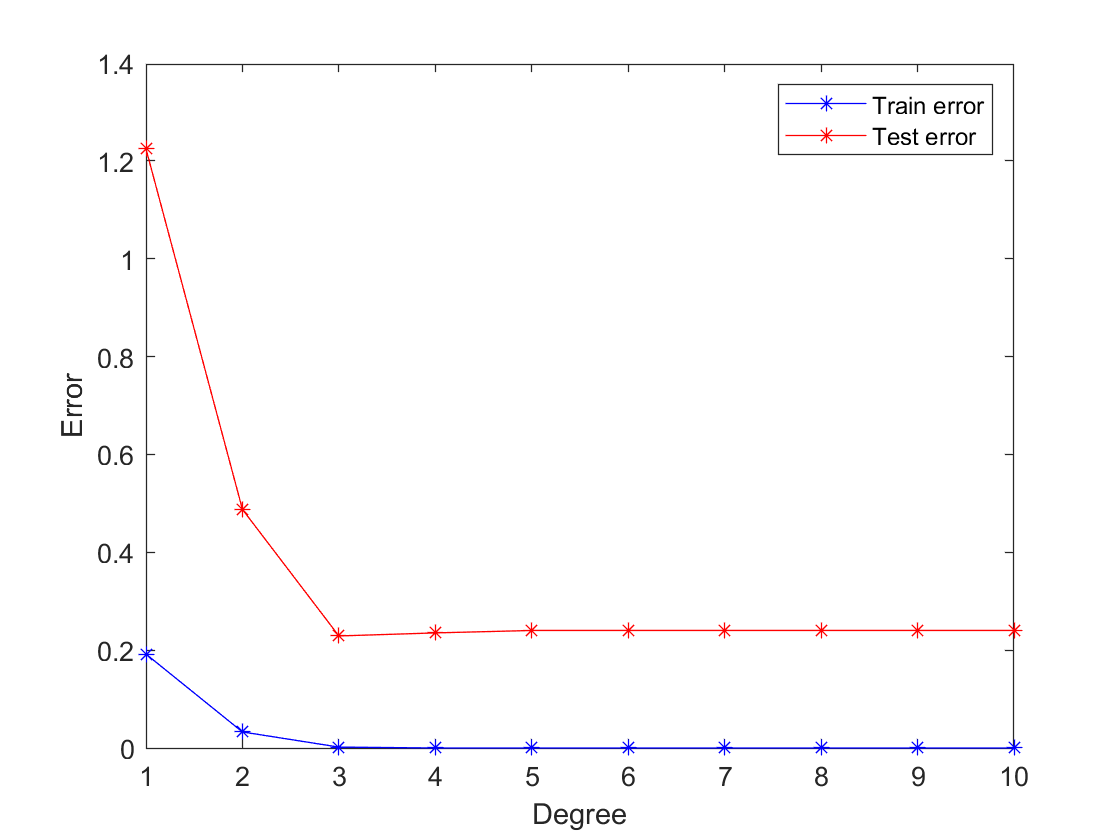


degrees = 1:10;

train_error = zeros(size(degrees));
test_error = zeros(size(degrees));

for i = 1:numel(degrees)
    p = polyfit(normalized_trainx, normalized_trainy, i);
    train_pred = polyval(p, normalized_trainx);
    test_pred = polyval(p, normalized_testx);
    train_error(i) = median((normalized_trainy - train_pred).^2);
    test_error(i) = median((normalized_testy - test_pred).^2);
end

figure
plot(degrees, train_error, 'b-*', degrees, test_error, 'r-*')
legend('Train error', 'Test error')
xlabel('Degree')
ylabel('Error')


display('با توجه به نموار از درجه 5 به بالا تغییر محسوسی در خطا حس نمیشود ولی پایینتر از آن خطا زیاد است')

با توجه به نموار از درجه 5 به بالا تغییر محسوسی در خطا حس نمیشود ولی پایینتر از آن خطا زیاد است


% Leat Squares implimentation

degree = 5;
X = zeros(length(x), degree);

for i = 1:degree
    X(:,i) = x(:).^i;
    
end

coeffs = X \ y(:);
disp(coeffs)

    7.3910
   10.0929
    0.6683
    0.2812
    3.2000



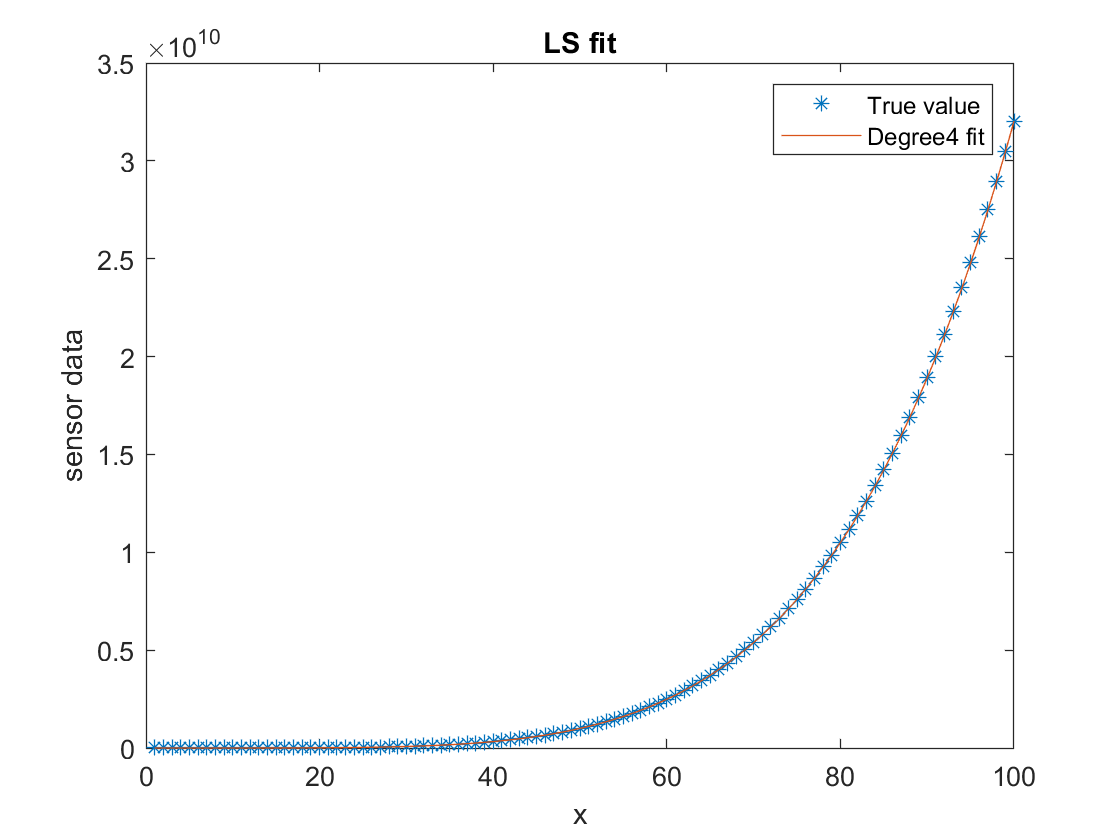


index = linspace(min(x), max(x), 500);
value = zeros(size(index));
for i = 1:degree
    value = value + coeffs(i)*index.^i;
end

figure
plot(x, y, '*', index, value, '-');
legend('True value', 'Degree4 fit');
xlabel('x');
ylabel('sensor data');
title('LS fit');

%RLS

%1
degree = 5;  % Degree of the polynomial

% Initialize variables
lambda_val = 1;
X = zeros(length(x), degree + 1);
for i = 0:degree
    X(:, i + 1) = x(:).^i;
end
P = eye(degree + 1) / lambda_val;
theta = zeros(degree + 1, 1);
coeffs = zeros(degree + 1, length(x));
tracee = zeros(length(x), 1);

% Recursive Least Squares (RLS) algorithm
for t = 1:length(x)
    k = P * X(t, :)' / (lambda_val + X(t, :) * P * X(t, :)');
    P = 1 / lambda_val * (P - k * X(t, :) * P);
    tracee(t) = trace(P);

    e = y(t) - X(t, :) * theta;
    theta = theta + k * e;
    coeffs(:, t) = theta;
end

disp(theta);

    5.8945
    6.3460
   10.1488
    0.6671
    0.2812
    3.2000



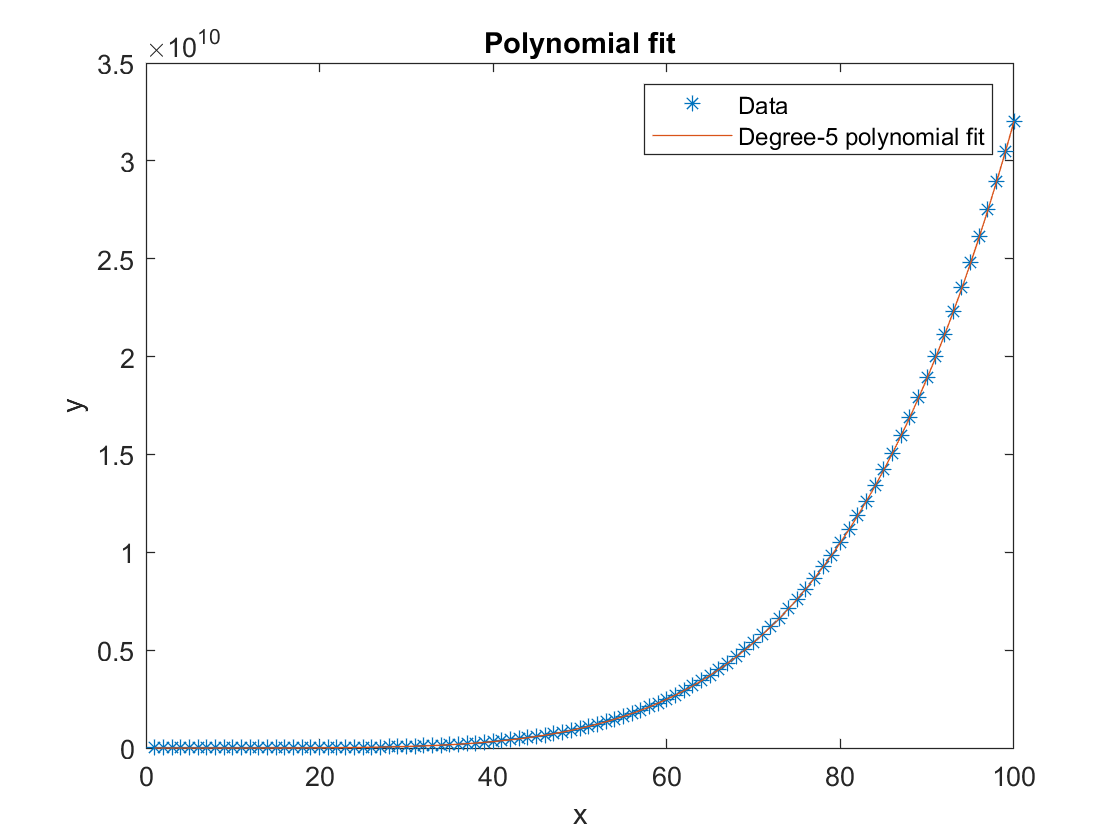


index = linspace(min(x), max(x), 500);
value = zeros(size(index));
for i = 0:degree
    value = value + coeffs(i + 1, end) * index.^i;
end

figure;
plot(x, y, '*', index, value, '-');
legend('Data', 'Degree-5 polynomial fit');
xlabel('x');
ylabel('y');
title('Polynomial fit');

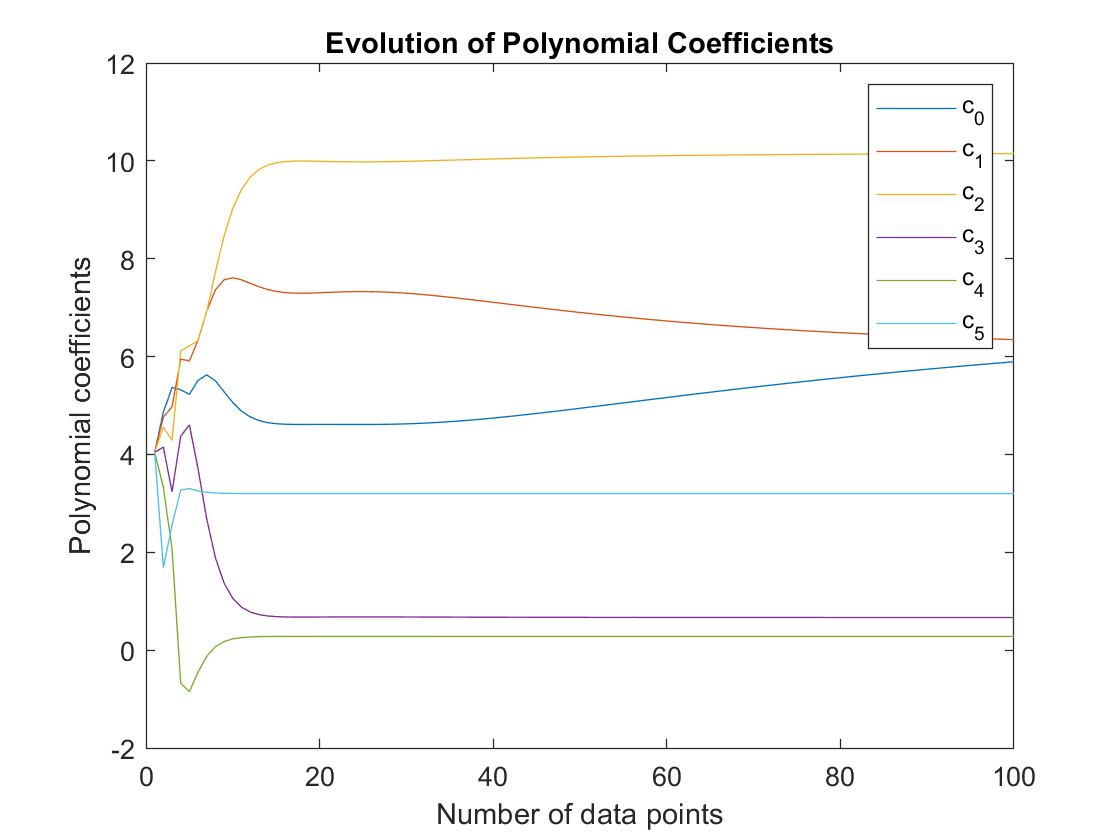


figure;
plot(1:length(x), coeffs');
xlabel('Number of data points');
ylabel('Polynomial coefficients');
legend('c_0', 'c_1', 'c_2', 'c_3', 'c_4', 'c_5');
title('Evolution of Polynomial Coefficients');

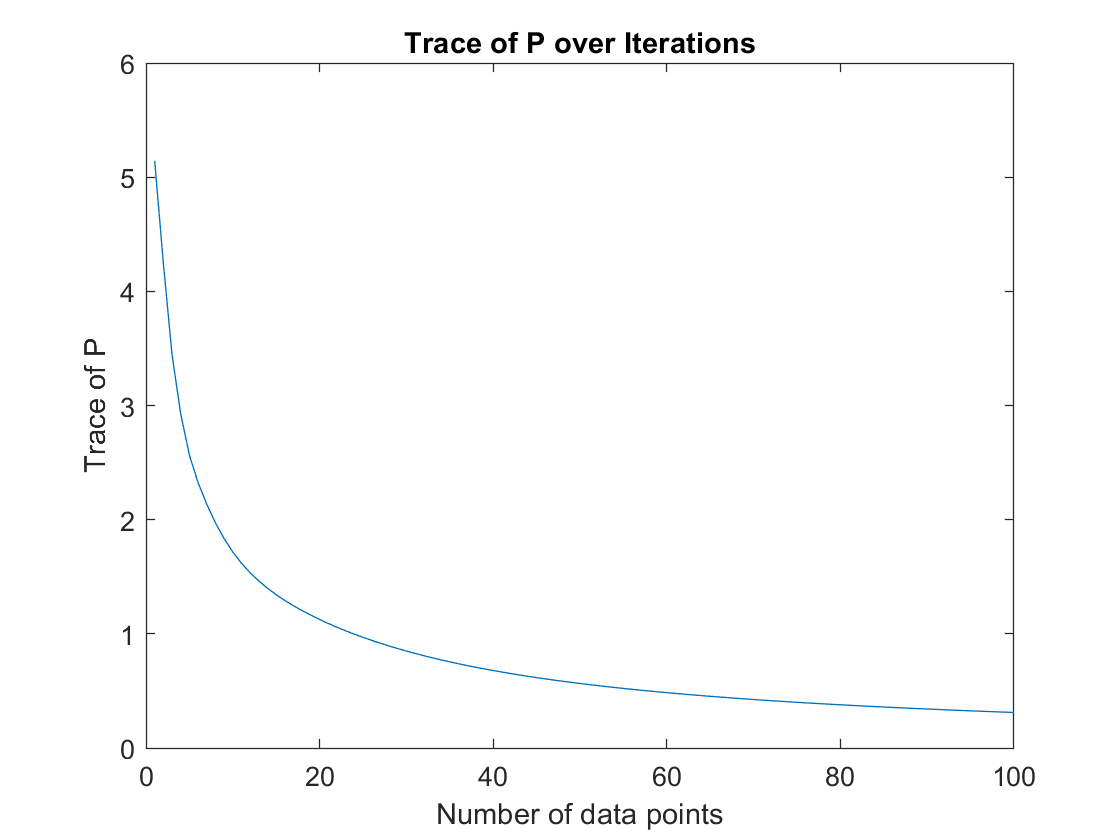


figure;
plot(1:length(x), tracee);
xlabel('Number of data points');
ylabel('Trace of P');
title('Trace of P over Iterations');

%2
degree = 5;  % Degree of the polynomial

% Initialize variables
lambda = 1;
a = 2;
X = zeros(length(x), degree + 1);
for i = 0:degree
    X(:, i + 1) = x(:).^i;
end
P = eye(degree + 1) / (lambda * a);
theta = zeros(degree + 1, 1);
coeffs = zeros(degree + 1, length(x));
tracee = zeros(length(x), 1);

% Recursive Least Squares (RLS) algorithm
for t = 1:length(x)
    k = P * X(t, :)' / (lambda + X(t, :) * P * X(t, :)');
    P = 1 / lambda * (P - k * X(t, :) * P);
    tracee(t) = trace(P);

    e = y(t) - X(t, :) * theta;
    theta = theta + k * e;
    coeffs(:, t) = theta;
end

disp(theta);

    4.7777
    6.5189
   10.1402
    0.6672
    0.2812
    3.2000




% Generate polynomial fit
index = linspace(min(x), max(x), 500);
value = zeros(size(index));
for i = 0:degree
    value = value + coeffs(i + 1, end) * index.^i;
end

% Plot results
figure;
plot(x, y, '*', index, value, '-');
legend('Data', 'Degree-5 polynomial fit');
xlabel('x');
ylabel('y');
title('Polynomial fit');

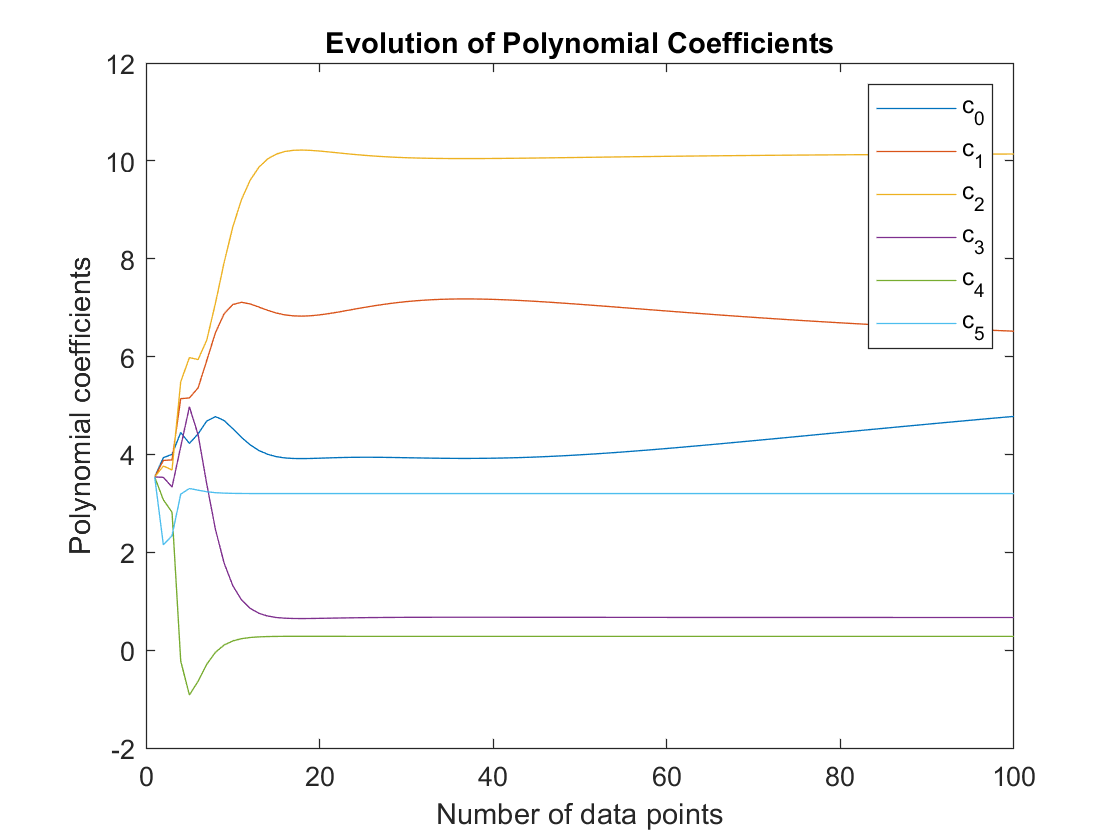


figure;
plot(1:length(x), coeffs');
xlabel('Number of data points');
ylabel('Polynomial coefficients');
legend('c_0', 'c_1', 'c_2', 'c_3', 'c_4', 'c_5');
title('Evolution of Polynomial Coefficients');

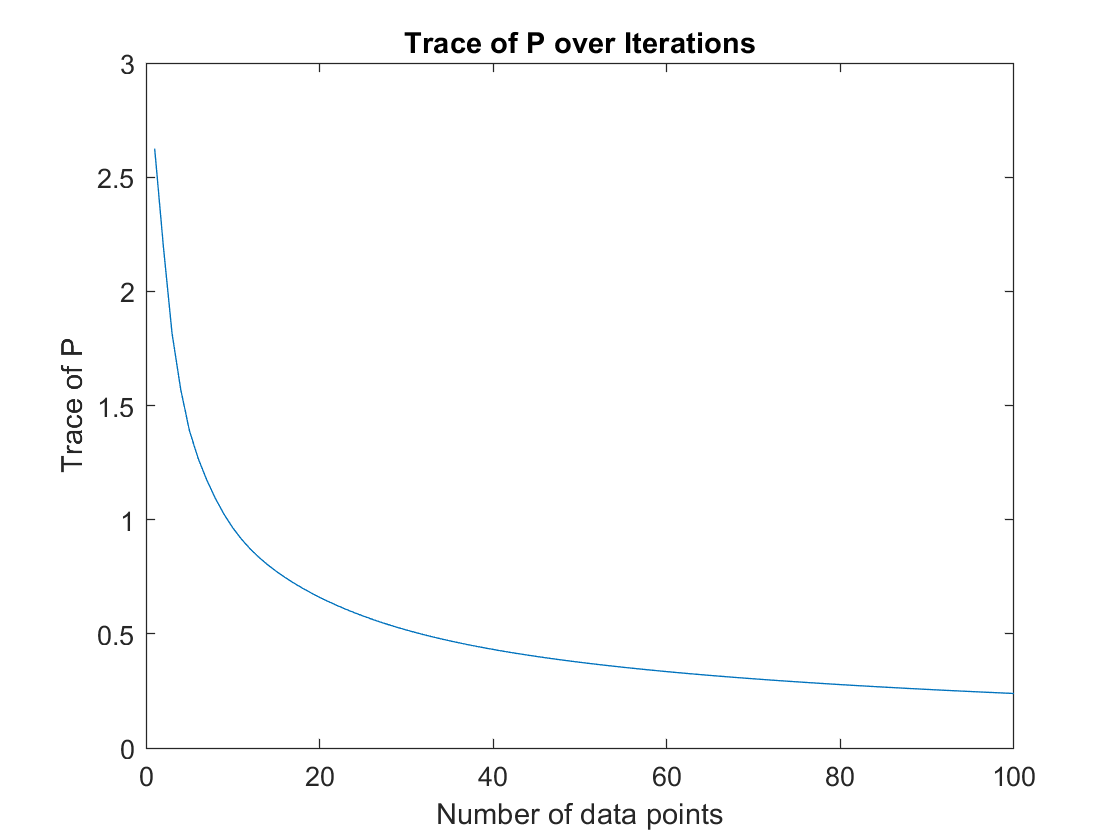


figure;
plot(1:length(x), tracee);
xlabel('Number of data points');
ylabel('Trace of P');
title('Trace of P over Iterations');

%3
degree = 5;  % Degree of the polynomial

% Initialize parameters
lambda = 1;
a = 4;
X = zeros(length(x), degree + 1);
for i = 0:degree
    X(:, i + 1) = x(:).^i;
end
P = eye(degree + 1) / (lambda * a);
theta = zeros(degree + 1, 1);
coeffs = zeros(degree + 1, length(x));
tracee = zeros(length(x), 1);

% Recursive Least Squares (RLS) algorithm
for t = 1:length(x)
    k = P * X(t, :)' / (lambda + X(t, :) * P * X(t, :)');
    P = 1 / lambda * (P - k * X(t, :) * P);
    tracee(t) = trace(P);

    e = y(t) - X(t, :) * theta;
    theta = theta + k * e;
    coeffs(:, t) = theta;
end

disp(theta);

    3.6124
    6.6778
   10.1329
    0.6674
    0.2812
    3.2000




% Generate polynomial fit
index = linspace(min(x), max(x), 500);
value = zeros(size(index));
for i = 0:degree
    value = value + coeffs(i + 1, end) * index.^i;
end

% Plot results
figure;
plot(x, y, '*', index, value, '-');
legend('Data', 'Degree-5 polynomial fit');
xlabel('x');
ylabel('y');
title('Polynomial fit');

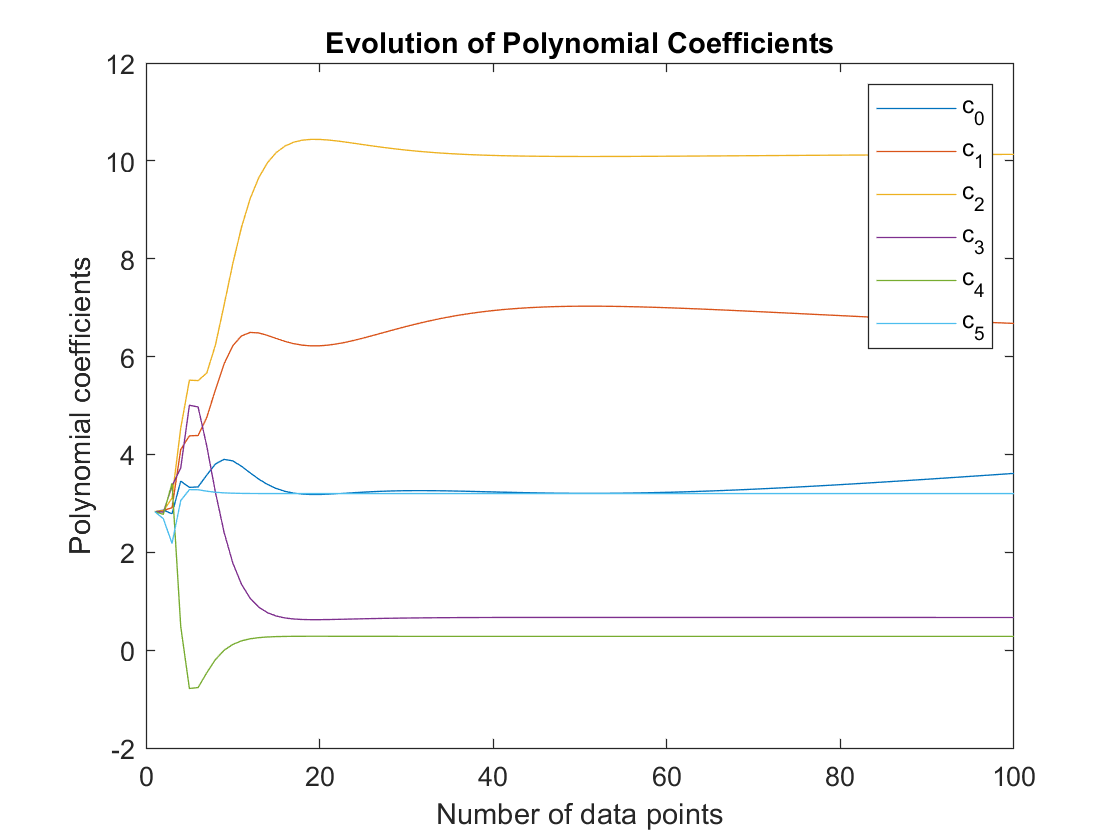


figure;
plot(1:length(x), coeffs');
xlabel('Number of data points');
ylabel('Polynomial coefficients');
legend('c_0', 'c_1', 'c_2', 'c_3', 'c_4', 'c_5');
title('Evolution of Polynomial Coefficients');

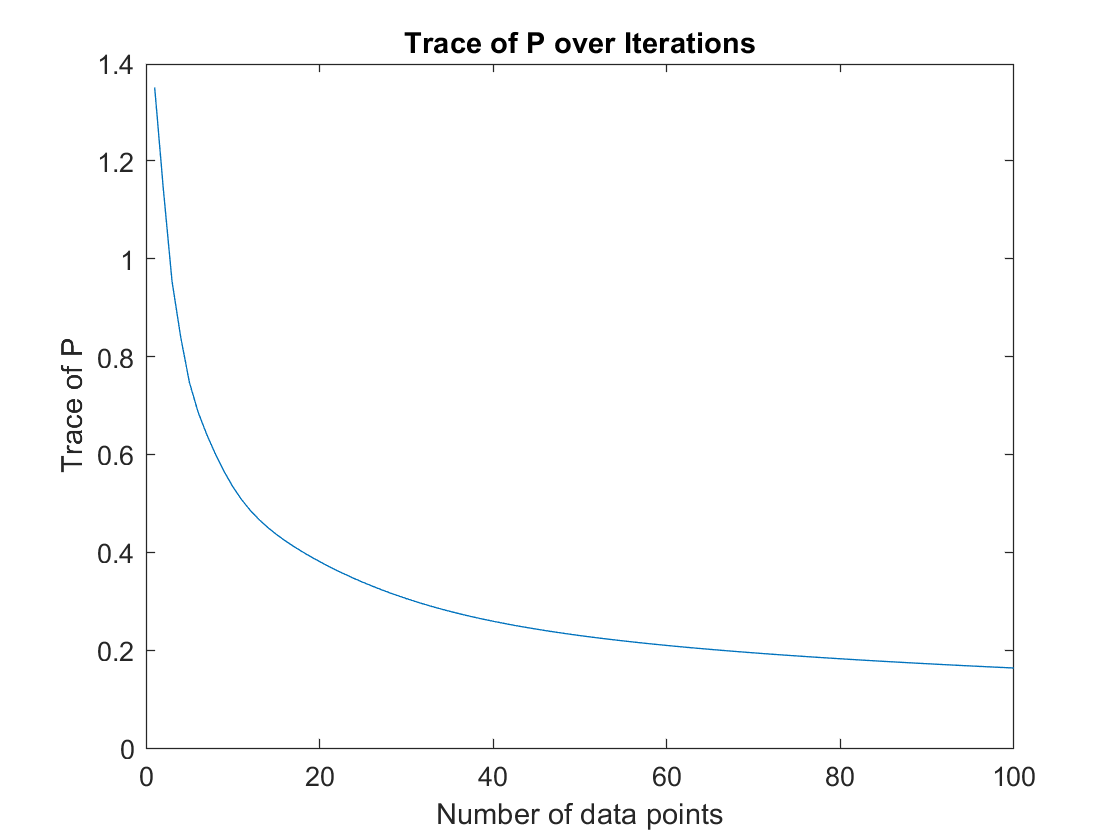


figure;
plot(1:length(x), tracee);
xlabel('Number of data points');
ylabel('Trace of P');
title('Trace of P over Iterations');

%4
degree = 5;  % Degree of the polynomial

% Initialize parameters
lambda = 1;
a = 69600;
X = zeros(length(x), degree + 1);
for i = 0:degree
    X(:, i + 1) = x(:).^i;
end
P = eye(degree + 1) / (lambda * a);
theta = zeros(degree + 1, 1);
coeffs = zeros(degree + 1, length(x));
tracee = zeros(length(x), 1);

% Recursive Least Squares (RLS) algorithm
for t = 1:length(x)
    k = P * X(t, :)' / (lambda + X(t, :) * P * X(t, :)');
    P = 1 / lambda * (P - k * X(t, :) * P);
    tracee(t) = trace(P);

    e = y(t) - X(t, :) * theta;
    theta = theta + k * e;
    coeffs(:, t) = theta;
end

% Display the estimated coefficients
disp(theta);

    0.0491
    0.7889
    9.5987
    0.6999
    0.2807
    3.2000



lennoi = length(x);
noise = randn(1,lennoi);

for i = 1:8:100
  disp(noise(i))
end

   -1.0059

    1.6321

   -1.7423

    0.8284

    1.3094

    0.7449

   -0.8984

   -0.1348

    0.2360

   -0.4977

    1.3396

   -0.6300

    0.6521



% LS
y = y + noise;  % Add noise to the target values
degree = 5;  % Degree of the polynomial

% Create the Vandermonde matrix
X = zeros(length(x), degree + 1);

for i = 0:degree
    X(:, i + 1) = x(:).^i;
end

% Estimate the polynomial coefficients using least squares
coeffs = X \ y(:);
disp(coeffs);

    7.3214
    6.0983
   10.1621
    0.6668
    0.2812
    3.2000




% Generate the polynomial fit
index = linspace(min(x), max(x), 500);
value = zeros(size(index));
for i = 0:degree
    value = value + coeffs(i + 1) * index.^i;
end

% Display the fitted polynomial
figure
plot(x, y, '*', index, value, '-');
legend('Data', 'Degree-5 polynomial fit');
xlabel('x');
ylabel('y');
title('Polynomial fit');

%RLS
lambda = 1;

X = zeros(length(x), degree+1);
for i = 0:degree
    X(:,i+1) = x(:).^i; 
end

P = eye(degree+1)/lambda;
theta = zeros(degree+1, 1);
coeffs = zeros(degree+1, length(x));
tracee = zeros(length(x), 1);

for t = 1:length(x)
    k = P * X(t,:)' / (lambda + X(t,:) * P * X(t,:)');
    P = 1/lambda * (P - k * X(t,:) * P);
    tracee(t) = trace(P); 
    
    e = y(t) - X(t,:) * theta;
    theta = theta + k * e;
    coeffs(:,t) = theta;
end

disp(theta)

    5.4235
    6.4080
   10.1462
    0.6671
    0.2812
    3.2000



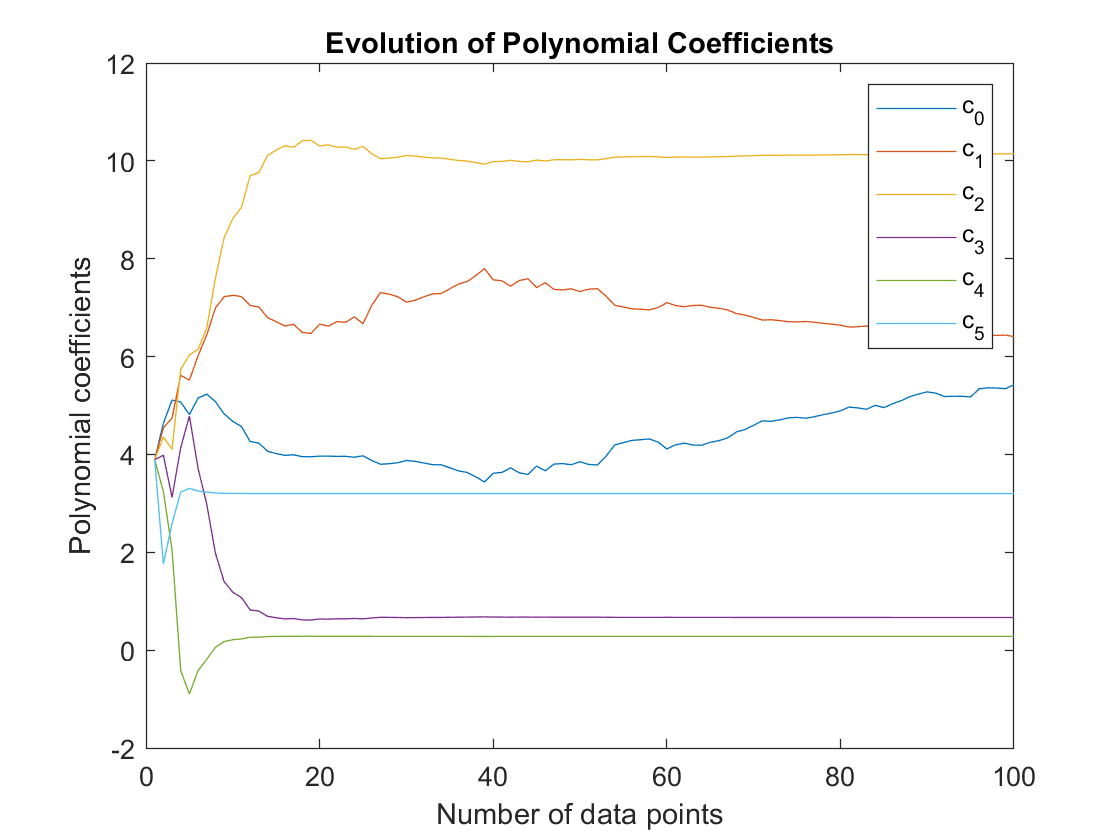


index = linspace(min(x), max(x), 500);
value = zeros(size(index));
for i = 0:degree
    value = value + coeffs(i+1,end)*index.^i;
end

figure;
plot(x, y, 'o', index, value, '-');
legend('Data', 'Degree-5 polynomial fit');
xlabel('x');
ylabel('y');
title('Polynomial fit');

figure;
plot(1:length(x), coeffs');
xlabel('Number of data points');
ylabel('Polynomial coefficients');
legend('c_0', 'c_1', 'c_2', 'c_3', 'c_4', 'c_5');
title('Evolution of Polynomial Coefficients');


figure;
plot(1:length(x), tracee);
xlabel('Number of data points');
ylabel('Trace of P');
title('Trace of P over Iterations');

%RLS
a=4;
lambda = 1;
X = zeros(length(x), degree+1);

for i = 0:degree
    X(:,i+1) = x(:).^i; 
end

P = eye(degree+1)/lambda*a;
theta = zeros(degree+1, 1);
coeffs = zeros(degree+1, length(x));
tracee = zeros(length(x), 1);

for t = 1:length(x)
    k = P * X(t,:)' / (lambda + X(t,:) * P * X(t,:)');
    P = 1/lambda * (P - k * X(t,:) * P);
    tracee(t) = trace(P); 
    
    e = y(t) - X(t,:) * theta;
    theta = theta + k * e;
    coeffs(:,t) = theta;
end

disp(theta)

    6.7049
    6.2006
   10.1568
    0.6669
    0.2812
    3.2000




index = linspace(min(x), max(x), 500);
value = zeros(size(index));
for i = 0:degree
    value = value + coeffs(i+1,end)*index.^i;
end

figure;
plot(x, y, '*', index, value, '-');
legend('Data', 'Degree-5 polynomial fit');
xlabel('x');
ylabel('y');
title('Polynomial fit');

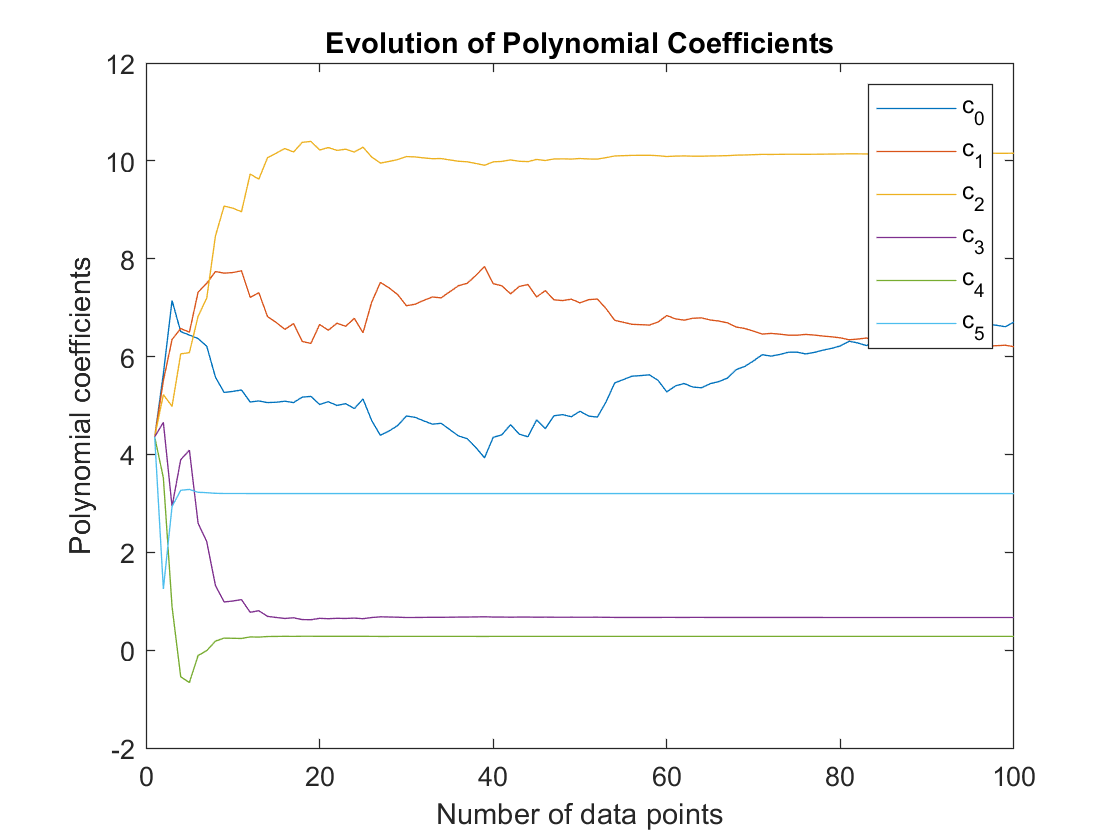


figure;
plot(1:length(x), coeffs');
xlabel('Number of data points');
ylabel('Polynomial coefficients');
legend('c_0', 'c_1', 'c_2', 'c_3', 'c_4', 'c_5');
title('Evolution of Polynomial Coefficients');

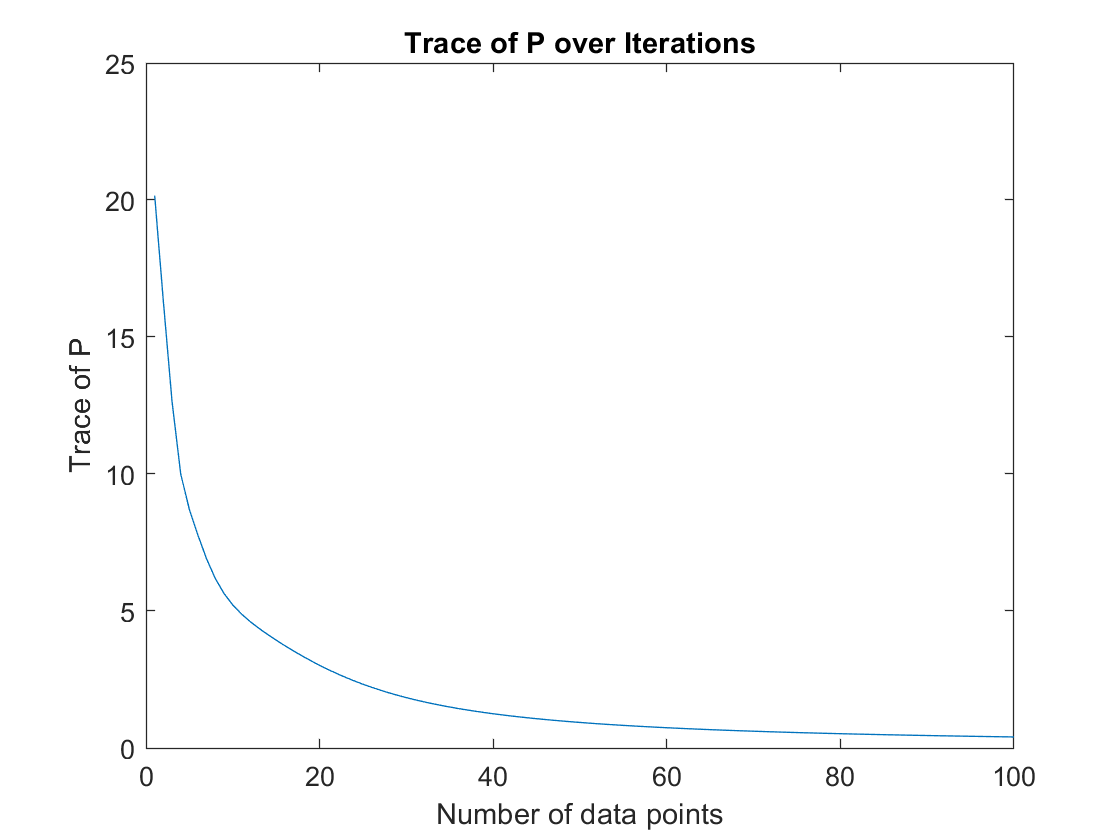


figure;
plot(1:length(x), tracee);
xlabel('Number of data points');
ylabel('Trace of P');
title('Trace of P over Iterations');

%RLS
a=62000;
lambda = 1;

X = zeros(length(x), degree+1);
for i = 0:degree
    X(:,i+1) = x(:).^i; 
end

P = eye(degree+1)/lambda*a;
theta = zeros(degree+1, 1);
coeffs = zeros(degree+1, length(x));
tracee = zeros(length(x), 1);

for t = 1:length(x)
    k = P * X(t,:)' / (lambda + X(t,:) * P * X(t,:)');
    P = 1/lambda * (P - k * X(t,:) * P);
    tracee(t) = trace(P);
    
    e = y(t) - X(t,:) * theta;
    theta = theta + k * e;
    coeffs(:,t) = theta;
end

disp(theta)

    7.3213
    6.0983
   10.1621
    0.6668
    0.2812
    3.2000

